# MATLAB TD1

### Nom Complet: Luiz Felipe SPINOLA SILVA

## Exercise 1 - Utilisation de find

Voir dans l'aide ce que signifie randn

Créer un vecteur u=randn(1,20)

Afficher u

Remplacer toutes les valeurs négatives de u par 0

Vérifier le résultat en affichant de nouveau le vecteur u

clc; clear; close all;
help("find")

 find - Find indices and values of nonzero elements
    This MATLAB function returns a vector containing the linear indices of
    each nonzero element in array X.

    Syntax
      k = find(X)
      k = find(X,n)
      k = find(X,n,direction)

      [row,col] = find(___)
      [row,col,v] = find(___)

    Input Arguments
      X - Input array
        scalar | vector | matrix | multidimensional array
      n - Number of nonzeros to find
        positive integer scalar
      direction - Search direction
        'first' (default) | 'last'

    Output Arguments
      

u = randn(1,20);
u

u =     1.8726    1.1297    0.2229   -1.4145    1.7395    0.0816    0.5255   -0.8856    2.0052   -0.1797    0.2643   -1.2512    1.5731    0.1492   -0.4782   -1.7789   -0.7795    0.7926    1.4913    1.6950


u(u<0) = 0;
u

u =     1.8726    1.1297    0.2229         0    1.7395    0.0816    0.5255         0    2.0052         0    0.2643         0    1.5731    0.1492         0         0         0    0.7926    1.4913    1.6950


## Exercice 2 : Conversion température

Sachant que C= (F - 32)*5/9, écrire dans un tableau une liste d'équivalence entre 0°F et 300°F, par pas de 10. La 1ère colonne contiendra les températures en °F, la seconde en °C Donner les valeurs en °F du tableau encadrant la température 0°C

temp_F = 0:10:300;
temp_C = (temp_F - 32)*5/9;
tab_temp = [temp_F; temp_C]';
tab_temp(find(tab_temp(:,2)<0, 1,"last"))

ans = 30

tab_temp(find(tab_temp(:,2)>0, 1,"first"))

ans = 40

## Exercice 3 : Création de matrices

Créer la matrice A contenant le vecteur [1 2 3 4] sur la diagonale et 0 ailleurs

Créer la matrice B=[0 0 0 4 0 0; 0 0 0 0 4 0; 0 0 0 0 0 4;4 0 0 0 0 0;0 4 0 0 0 0;0 0 4 0 0 0] (autrement

que comme cela!)

Créer la matrice C de taille 4*5 contenant tous les nombres de 1 à 20

Afficher la taille de C pour vérifier que vous avez bien une matrice 4*5

Donner la valeur du premier élément de la 4ème ligne de C

Donner la valeur du dernier élément de la 5ème colonne de C

Extraire la 2ème ligne de C

Extraire la 3ème colonne de C

Extraire la dernière ligne de C

Extraire de la 4ème ligne de C les éléments de 3 à 5

Créer la matrice D, transposée de C

Extraire à partir de D le vecteur E ne contenant que les nombres pairs de D

Extraire à partir de D le vecteur F ne contenant que les nombres impairs de D

Concaténer les vecteurs E et F pour en faire une matrice G de taille 2*10

A = diag([1 2 3 4])

A =      1     0     0     0
     0     2     0     0
     0     0     3     0
     0     0     0     4


B = (diag([4 4 4],3))+(diag([4 4 4],-3))

B =      0     0     0     4     0     0
     0     0     0     0     4     0
     0     0     0     0     0     4
     4     0     0     0     0     0
     0     4     0     0     0     0
     0     0     4     0     0     0


C = reshape(1:1:20,[4 5])

C =      1     5     9    13    17
     2     6    10    14    18
     3     7    11    15    19
     4     8    12    16    20


C(4,1)

ans = 4

C(:,3)

ans =      9
    10
    11
    12


C(end,:)

ans =      4     8    12    16    20


C(4,(3:5))

ans =     12    16    20


D = C'

D =      1     2     3     4
     5     6     7     8
     9    10    11    12
    13    14    15    16
    17    18    19    20


E = D(rem(D,2)==0)

E =      2
     6
    10
    14
    18
     4
     8
    12
    16
    20


F = D(rem(D,2)~=0)

F =      1
     5
     9
    13
    17
     3
     7
    11
    15
    19


G = [E';F']

G =      2     6    10    14    18     4     8    12    16    20
     1     5     9    13    17     3     7    11    15    19


## Exercice 4 : Matrice diagonale

Soit A une matrice carrée quelconque à choisir.

Construire en une ligne de commande une matrice B ayant la même diagonale que A et des 0 autour.

A = 5.*rand([3 3])

A =     3.1414    1.1370    0.6014
    4.5755    1.6376    4.8445
    4.1957    2.0338    2.2478


B = diag(diag(A))

B =     3.1414         0         0
         0    1.6376         0
         0         0    2.2478


## Exercice 5 : Fonction et création de matrices

Ecrire une fonction qui étant donnée une matrice A et un entier n permet de modifier A en remplaçant sa nième colonne par les valeurs opposées à celles initialement présentes.

Attention à la valeur de n, renvoyer un message d'erreur en cas de problème de taille.

Remarque : il est possible de le faire sans boucle…

Ne pas oublier de mettre un commentaire décrivant l'usage de la fonction

function new_matrix = oppose_collumn(A, n)
%invert the values from collumn n
%get the number of collumns of A

if n>size(A,2)
    error('Column index n must be a positive integer and less than or equal to the number of columns in A.');
end
var = A; 
var(:, n) = -var(:, n);
new_matrix = var;
end

A_opposite = oppose_collumn(A,2)

A_opposite =     3.1414   -1.1370    0.6014
    4.5755   -1.6376    4.8445
    4.1957   -2.0338    2.2478


## Exercice 6 : Modification de noms de fichiers

Ecrire une fonction permettant de renommer un fichier (on suppose que l'extension contient 3 lettres, ex.txt, .xls, .doc) en un fichier avec le même nom générique et une extension .dat.

Exemple : le fichier toto.txt devient toto.dat

Aide : il suffit de lire des chaînes de caractères et de modifier les 3 derniers caractères…

Ne pas oublier de mettre un commentaire décrivant l'usage de la fonction

function newfile = change_file_extension(filename)
% filename is a string, change its last three characters to "dat"
newfile = split(filename, ".");
newfile = strcat(newfile{1}, ".dat");
end

file_example = 'arquivo.wav'

file_example = 'arquivo.wav'

file_new_format = change_file_extension(file_example)

file_new_format = "arquivo.dat"

## Exercice 7 : Nom de fichiers

Ecrire une fonction qui étant donnés un nom de fichier (avec une extension de 3 lettres) et un entier n, affiche à l'écran le nom générique du fichier, suivi du numéro et de l'extension. Exemple: toto.txt et n=3, affichage attendu: toto1.txt, toto2.txt, toto3.txt

function file_list = more_files(filename,n)

file_list = ["", "" ,""];
file_var = split(filename, ".");
file_name = file_var{1};
file_format = file_var{2};
for i = 1:n
    file_list(i) = append(file_name, int2str(i), ".", file_format);
end
end

file_example = "arquivo_novo.wav"

file_example = "arquivo_novo.wav"

file_list = more_files(file_example, 5)

file_list = 1×5 string array
    "arquivo_novo1.wav"    "arquivo_novo2.wav"    "arquivo_novo3.wav"    "arquivo_novo4.wav"    "arquivo_novo5.wav"


## Exercice 8 : Manipulation Matrices

Créer une matrice A carrée de taille 100 avec des zéros à l'intérieur.

Créer une matrice B de même taille que A mais avec les 1.

Créer une matrice C avec les nombres entiers aléatoires de 0 à 255 de la même taille que A.

Créer une matrice D de taille 100*300 en concaténant les matrices A, B et C.

A partir de D et avec la fonction reshape (cf l'aide) créer une matrice I de taille 100x100x3 (matrice à

3 dimensions)

Afficher avec la fonction disp (cf l'aide) la taille de la matrice I : la taille de la matrice I est ….

Afficher la valeur qui se trouve sur la ligne 50 et colonne 50 dans chacune des 3 dimensions.

A = zeros(100);
B = ones(100);
C = randi([0 255], size(A, 1));
D = [A B C];
I = reshape(D, [100 100 3]);
disp(size(I));

   100   100     3



disp(I(50,50,1));

     0



disp(I(50,50,2));

     1



disp(I(50,50,3));

    19



## Exercice 9 : Manipulation de matrices (annales décembre 2018)

1. Créer une matrice A de taille 10x10 contenant des entiers aléatoirement choisis entre 1 et 8 (voir fonction randi). Si vous n'y arrivez pas, créer à la main cette matrice afin de pouvoir continuer l'exercice.

2. Remplacer tous les nombres compris entre la 3ème ligne et la 5ème ligne par des 2

3. Créer un vecteur ligne U de taille 1x10 contenant des multiples de 5 (en commençant à 5)

4. Rajouter une ligne à A contenant le vecteur U.

5. A partir de U, créer le vecteur colonne V de taille 11x1 contenant des multiples de 5 (en commençant par 5)

6. Rajouter une colonne à A contenant le vecteur V

7. Quelle commande permet de connaître le nombre de lignes et de colonnes de A ? Donner les valeurs

8. Remplacer tous les 5 de la matrice A par la valeur 0

9. Ecrire une ligne de commande permettant de compter le nombre d'occurrences de 2 dans la matrice

A (sans les compter manuellement)

10. Tracer sur un graphe les valeurs de la 1ere ligne de A en fonction de la dernière colonne de A

11. Rajouter sur cette figure le graphe présentant les valeurs de la 4ème colonne de A en fonction de V,

avec une autre couleur, un autre symbole et un autre type de trait

A = randi([1 8], [10 10]);
A(3,:) = 2;
A(5,:) = 2;
U = 5:5:(5*10);
A(1,:) = U;
V = [U (5*11)]';
A(11, 11) = 0;
A(:,end) = V;
size(A)

ans =     11    11


A(A == 5) = 0;
sum(A == 2)

ans =      3     3     3     3     2     3     3     5     3     2     0


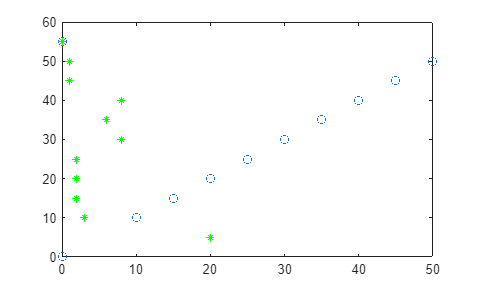

plot(A(1,:), A(:,end), 'o')
hold on
plot(A(:,4), V, '*', Color="g")

## Exercice 10 : Fonction et création de matrices (2)

Ecrire une fonction qui étant donné un nombre n permet de créer la matrice carrée A de dimension (n+1) contenant les multiples de n sur la 1ere diagonale au-dessus de la diagonale principale et 1/n, 2/n, 3/n

… au-dessous de la diagonale principale.

Remarque : il est possible de le faire sans boucle…

Mettre un commentaire général permettant de décrire ce que fait la fonction. Quelle commande permet

de voir ce descriptif dans la fenêtre de commande ?

function M = diag_multiples(n)
% étant donné un nombre n permet de créer la matrice carrée A de dimension (n+1)
%contenant les multiples de n sur la 1ere diagonale au-dessus de la diagonale principale et 1/n, 2/n, 3/n
%… au-dessous de la diagonale principale.
M = n:n:(n*(n));
M = diag(M,1);
% for i = 1:n
%     N = (i/n):(i/n):(((n+1)-i)*(i/n));
%     N = diag(N,-i);
%     M = M + N;
% end
N = (1/n):(1/n):(((n+1)-1)*(1/n));
N = diag(N,-1);
M = M + N;
end

test = diag_multiples(4)

test =          0    4.0000         0         0         0
    0.2500         0    8.0000         0         0
         0    0.5000         0   12.0000         0
         0         0    0.7500         0   16.0000
         0         0         0    1.0000         0


## Exercice 11 : Manipulation de matrices (annales avril 2016)

1. Définir le vecteur v = [0 1 2 3 … 49] autrement que par cette (longue !) énumération

2. Définir le vecteur x contenant les 5 premiers et les 5 derniers éléments de v

3. Définir le vecteur z = [0 2 4… 48] à partir de v

4. Définir la matrice M = [1 2 3 4 5 6 7 8 9 10 ; 11 12 13 14 15 16 17 18 19 20 ;21 22 23 24 25 26 27 28

29 30], autrement que par cette (longue !) énumération

5. Donner la commande permettant de récupérer ses dimensions

6. Extraire de M la matrice N = [1 2 ;11 12 ;21 22]

7. Extraire de M la matrice P = [3 23;7 27]

v = 0:1:49;
x = [v(1:5) v(end-4:end)]

x =      0     1     2     3     4    45    46    47    48    49


z = v((rem(v,2)==0))

z =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48


M = [1:10; 11:20; 21:30]

M =      1     2     3     4     5     6     7     8     9    10
    11    12    13    14    15    16    17    18    19    20
    21    22    23    24    25    26    27    28    29    30


size(M)

ans =      3    10


N = M(1:3, 1:2)

N =      1     2
    11    12
    21    22


P = M(1:2:3, 3:4:7)'

P =      3    23
     7    27


## Exercice 12 : Manipulation de matrices (annales avril 2017)

1. Créer une matrice M de 6 lignes et 5 colonnes avec des nombres aléatoires compris entre 0 et 1

exclus.

2. Transformer M pour que ses nombres soient des entiers compris entre 0 et 20 exclus. (Si vous n'y

arrivez pas facilement, imaginez-en une et remplissez-la vous-même à la main).

3. Quelle commande permet d'obtenir le nombre de lignes et le nombre de colonnes de M ?

4. Donner la valeur maximale de M

5. Comment obtenir le nombre de fois qu'apparaît cette valeur max dans M ?

6. Remplacer toutes les occurrences de la valeur max par -3

7. Extraire de M la matrice P contenant la 2ème et la 4ème ligne de M

8. Tracer sur un graphe la deuxième ligne de P en fonction de la première ligne avec des marqueurs

carrés rouge. Ajouter la grille

9. Extraire de M la matrice Q contenant de la 3ème à la dernière ligne de M et de la 2ème à la 3ème colonne

de M

10. Créer une matrice R dont la première ligne est la première ligne de P, les lignes suivantes contiennent

Q et des 1 dans les « trous », et la dernière ligne est la dernière ligne de P. Par exemple si P=[1 2 3 4 5 ;

6 7 8 9 10] ; Q=[4 5 ;7 8 ; 11 12 ;18 19] alors R=[1 2 3 4 5 ; 4 5 1 1 1 ; 7 8 1 1 1 ;11 12 1 1 1 ;18 19 1 1

1 ; 6 7 8 9 10]

11. Copier R dans T et remplacer dans T toutes les valeurs différentes de 1 par 0.

12. Ecrire une fonction qui à partir d'une matrice donnée, transforme toutes les valeurs x en une valeur

y et retourne la matrice résultat.

13. L'appeler sur la matrice T pour remplacer tous les 0 par -1

M = randi([0 1], [6 5]);
M = randi([0 20], [6 5])

M =      6    19     4     7    14
     5     6     6     3     6
     7     5     8     2     2
     8    15     3    20     1
     9    17     0    16    16
    13    19     3     3    11


size(M)

ans =      6     5


maxm = max(M(:))

maxm = 20

sum((M(:) == maxm))

ans = 1

M(M(:) == maxm) = -3

M =      6    19     4     7    14
     5     6     6     3     6
     7     5     8     2     2
     8    15     3    -3     1
     9    17     0    16    16
    13    19     3     3    11


P = M(2:2:4,:)

P =      5     6     6     3     6
     8    15     3    -3     1


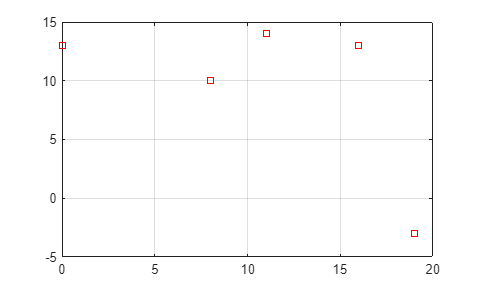

figure()
plot(P(2,:), P(1,:), "square", Color = "r")
grid on

Q = M(3:end,2:3)

Q =      5     8
    15     3
    17     0
    19     3


R = ones([6 5]);
R(1,:) = P(1,:);
R(2:end-1,1:2) = Q;
R(end,:) = P(end,:)

R =      5     6     6     3     6
     5     8     1     1     1
    15     3     1     1     1
    17     0     1     1     1
    19     3     1     1     1
     8    15     3    -3     1


T = R;
T(T~=1) = 0

T =      0     0     0     0     0
     0     0     1     1     1
     0     0     1     1     1
     0     0     1     1     1
     0     0     1     1     1
     0     0     0     0     1


function new_matrix = change_matrix(m,x,y)
% partir d’une matrice donnée, transforme toutes les valeurs x en une valeur y et retourne la matrice résultat.
new_matrix = m;
new_matrix(new_matrix == x) = y;
end

T = change_matrix(T,0,-1)

T =     -1    -1    -1    -1    -1
    -1    -1     1     1     1
    -1    -1     1     1     1
    -1    -1     1     1     1
    -1    -1     1     1     1
    -1    -1    -1    -1     1
